clear
load('./traces_v7/input_sets_second_op_char_31_2.mat');

%Settings for the dataset
numberOfSets = 1000;
setSize = 31;
totalComparisons = numberOfSets * (numberOfSets-1) / 2;
category = cell(1,totalComparisons);
val = zeros(1,totalComparisons);
inputComparison = inputs_b(1:31:size(inputs_b,1),:);
freq = 100e6;
samplesPerSec = 40e9;
samplesPerCycle = samplesPerSec/freq;
compressTraceSize = ceil(size(traces_Y,2)/samplesPerCycle);
clockIndexes = getClockIndexesShort();

meanTraces = getMeanTraces(traces_Y,numberOfSets,setSize);

## **Correlation**

%Test 1.1
index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        corrMat = corrcoef(meanTraces(i,:),meanTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

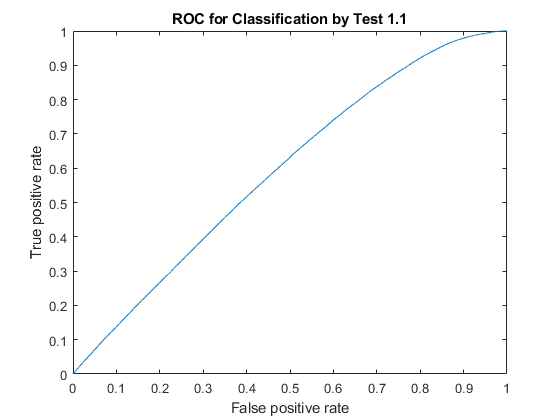

[X11,Y11,T11,AUC11] = perfcurve(category',val','same');
plot(X11,Y11)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.1')
hold off

%Test 1.2
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

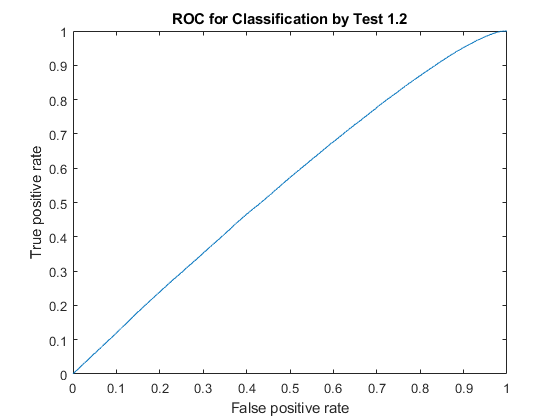

[X12,Y12,T12,AUC12] = perfcurve(category',val','same');
plot(X12,Y12)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.2')
hold off

% Test 1.3
category = cell(1,totalComparisons);
compressTraces = compressAvgWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

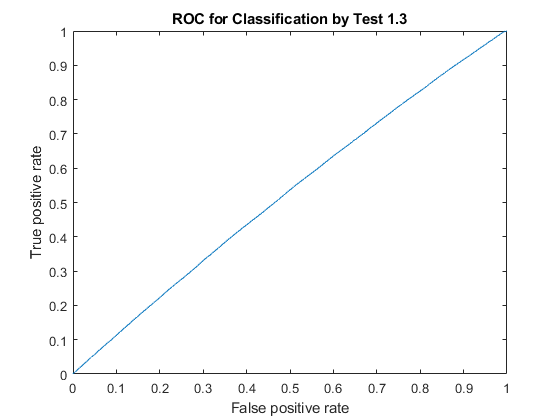

[X13,Y13,T13,AUC13] = perfcurve(category',val','same');
plot(X13,Y13)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.3')
hold off

% Test 1.4 
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

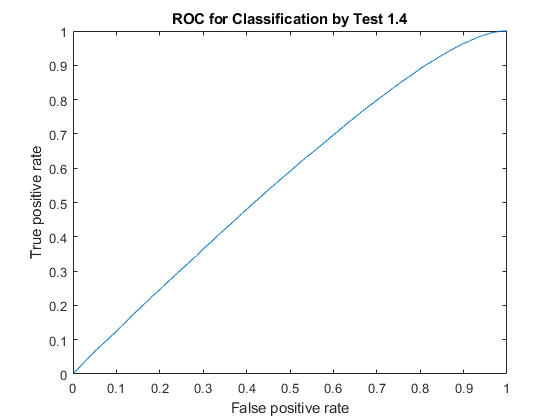

[X14,Y14,T14,AUC14] = perfcurve(category',val','same');
plot(X14,Y14)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.4')
hold off

% Test 1.5 
category = cell(1,totalComparisons);
compressTraces = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

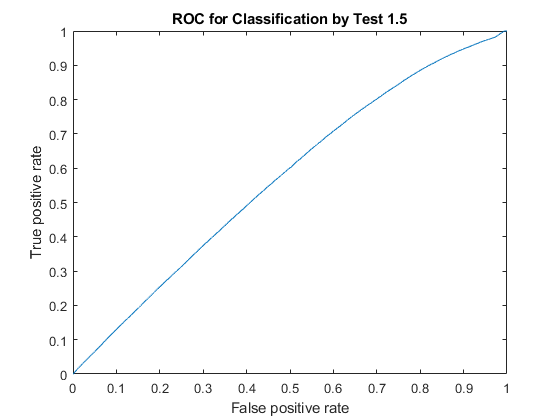

[X15,Y15,T15,AUC15] = perfcurve(category',val','same');
plot(X15,Y15)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.5')
hold off

## **Euclidean distance**

%Test 2.1
category = cell(1,totalComparisons);
index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        index = index + 1;
        val(index) = norm(meanTraces(i,:) - meanTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

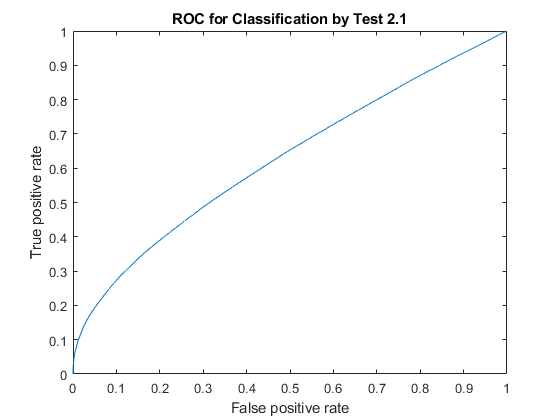

[X21,Y21,T21,AUC21] = perfcurve(category',val','different');
plot(X21,Y21)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.1')
hold off

%Test 2.2
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

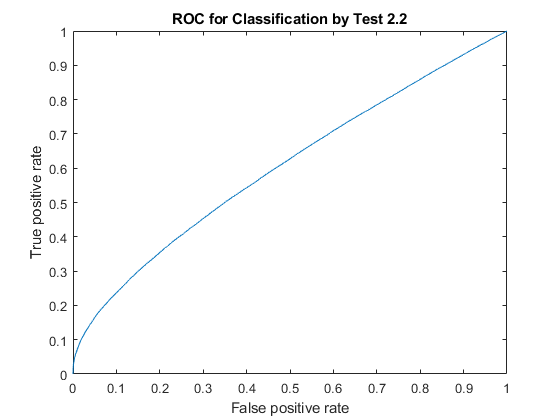

[X22,Y22,T22,AUC22] = perfcurve(category',val','different');
plot(X22,Y22)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.2')
hold off

%Test 2.3
category = cell(1,totalComparisons);
compressTraces = compressAvgWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

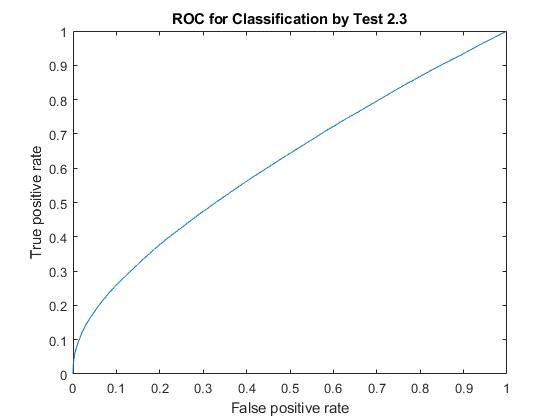

[X23,Y23,T23,AUC23] = perfcurve(category',val','different');
plot(X23,Y23)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.3')
hold off

%Test 2.4
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

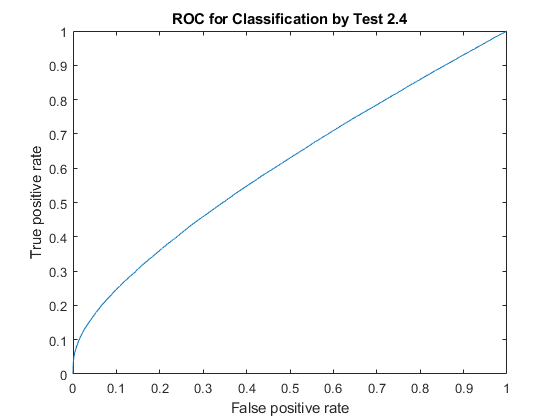

[X24,Y24,T24,AUC24] = perfcurve(category',val','different');
plot(X24,Y24)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.4')
hold off

%Test 2.5
category = cell(1,totalComparisons);
compressTraces = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

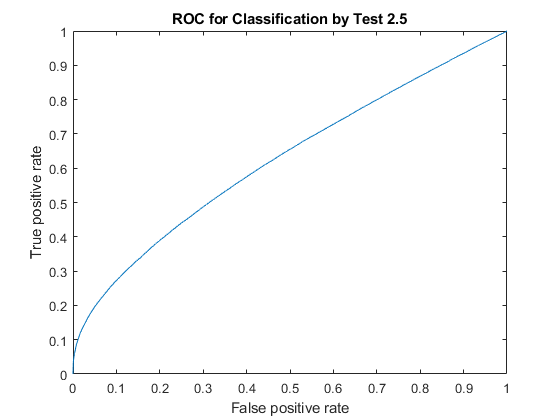

[X25,Y25,T25,AUC25] = perfcurve(category',val','different');
plot(X25,Y25)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.5')
hold off

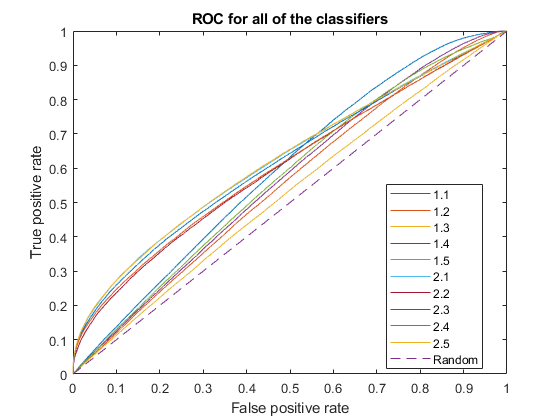

%Plot all of them 
plot(X11,Y11)
hold on
plot(X12,Y12)
plot(X13,Y13)
plot(X14,Y14)
plot(X15,Y15)
plot(X21,Y21)
plot(X22,Y22)
plot(X23,Y23)
plot(X24,Y24)
plot(X25,Y25)
plot(0:1,0:1,'--')
legend('1.1','1.2','1.3','1.4','1.5','2.1','2.2','2.3','2.4','2.5','Random','Location','Best')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for all of the classifiers')
hold off

AUC11

AUC11 = 0.5937

AUC12

AUC12 = 0.5535

AUC13

AUC13 = 0.5251

AUC14

AUC14 = 0.5667

AUC15

AUC15 = 0.5699

AUC21

AUC21 = 0.6261

AUC22

AUC22 = 0.6043

AUC23

AUC23 = 0.6186

AUC24

AUC24 = 0.6076

AUC25

AUC25 = 0.6265

clearvars -except -regexp ^([XYT])\d{2}